# All-Files Analysis

## Import All Data

clear;

datasets = dir('data/*.mat');
numfiles = length(datasets);
% numfiles = 2
mydata = cell(1, numfiles);

% Import Data
for k = 1:numfiles
  mydata{k} = importdata(strcat('data/',datasets(k).name));
  mydata{k}.Source = datasets(k).name;
end

% Run simple analysis on all
% for k = 1:length(mydata)
%     sample = mydata(k);
%     Acceleration = sample{1}.Acceleration;
%     figure()
%     stackedplot(Acceleration);
%     title({'Time table visualization of printhead acceleration';strcat('\fontsize{8}\itFile:  ',sample{1}.Source)})
% end

## Plot All Data

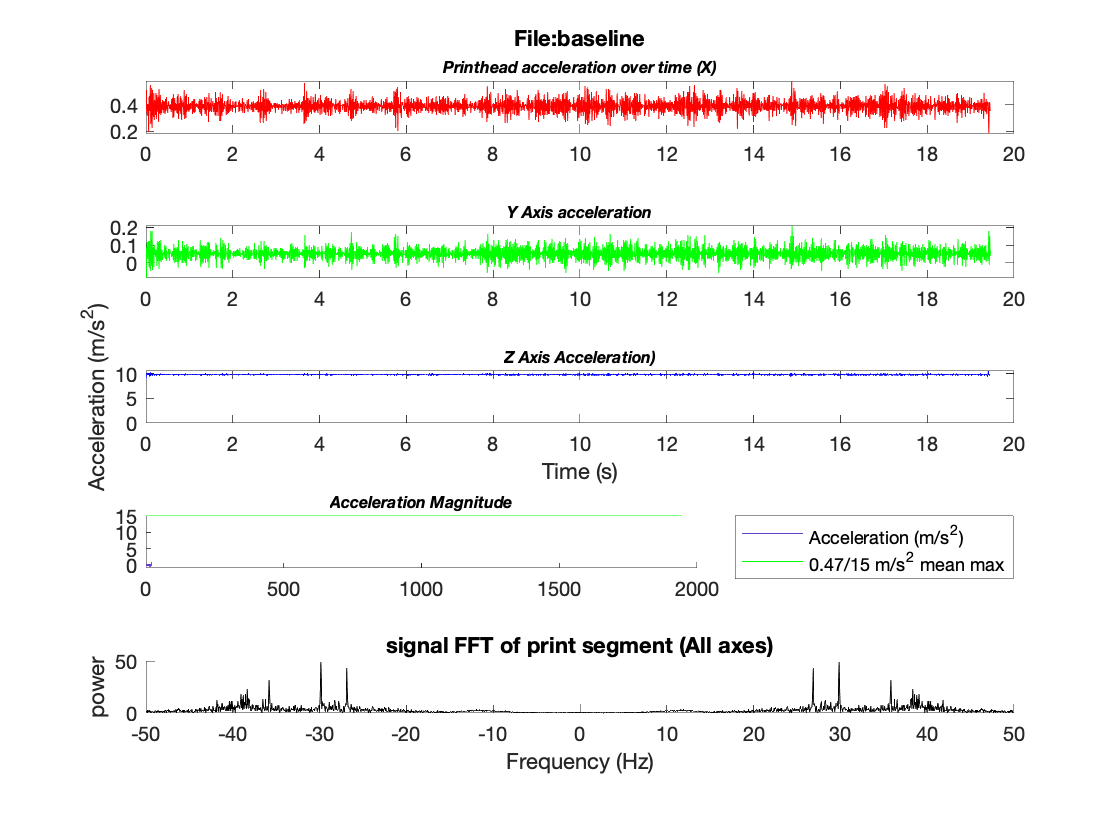

largest =     0.0253    0.0253    0.0221


success = logical
   0


success = logical
   0


level = 0.0242

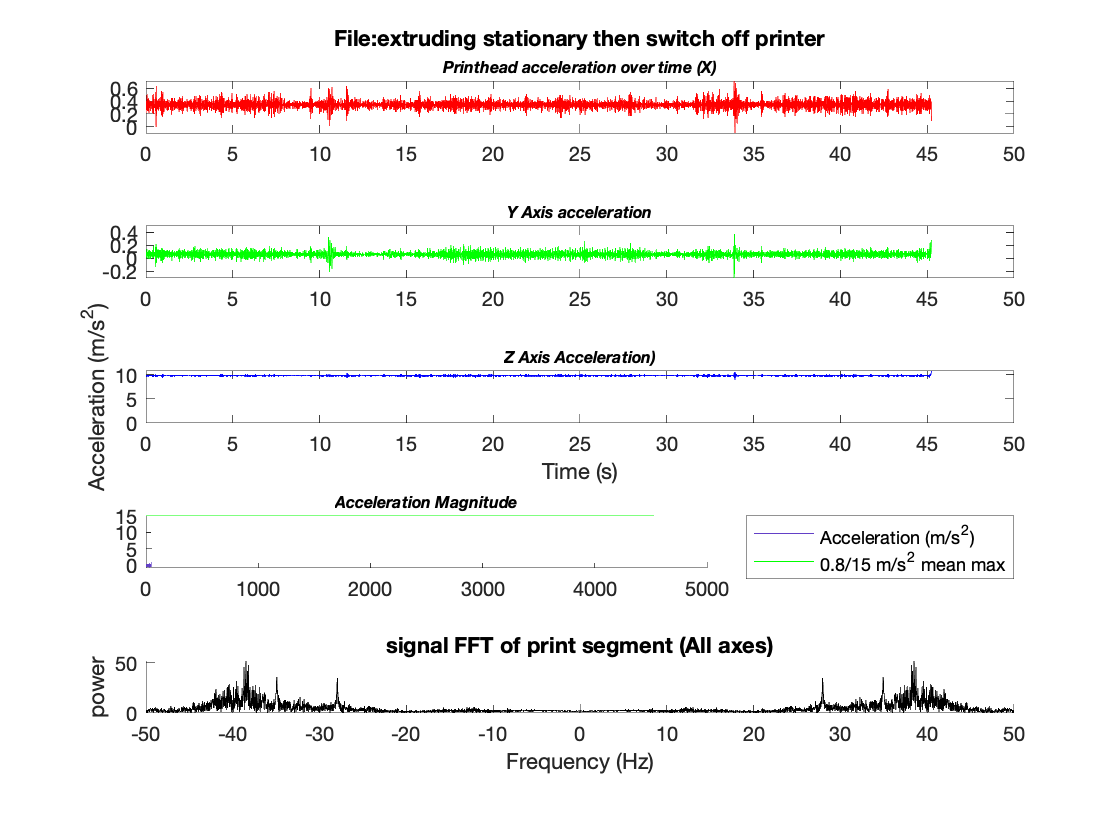

largest =     0.0075    0.0075    0.0068


success = logical
   1


success = logical
   1


level = 0.0073

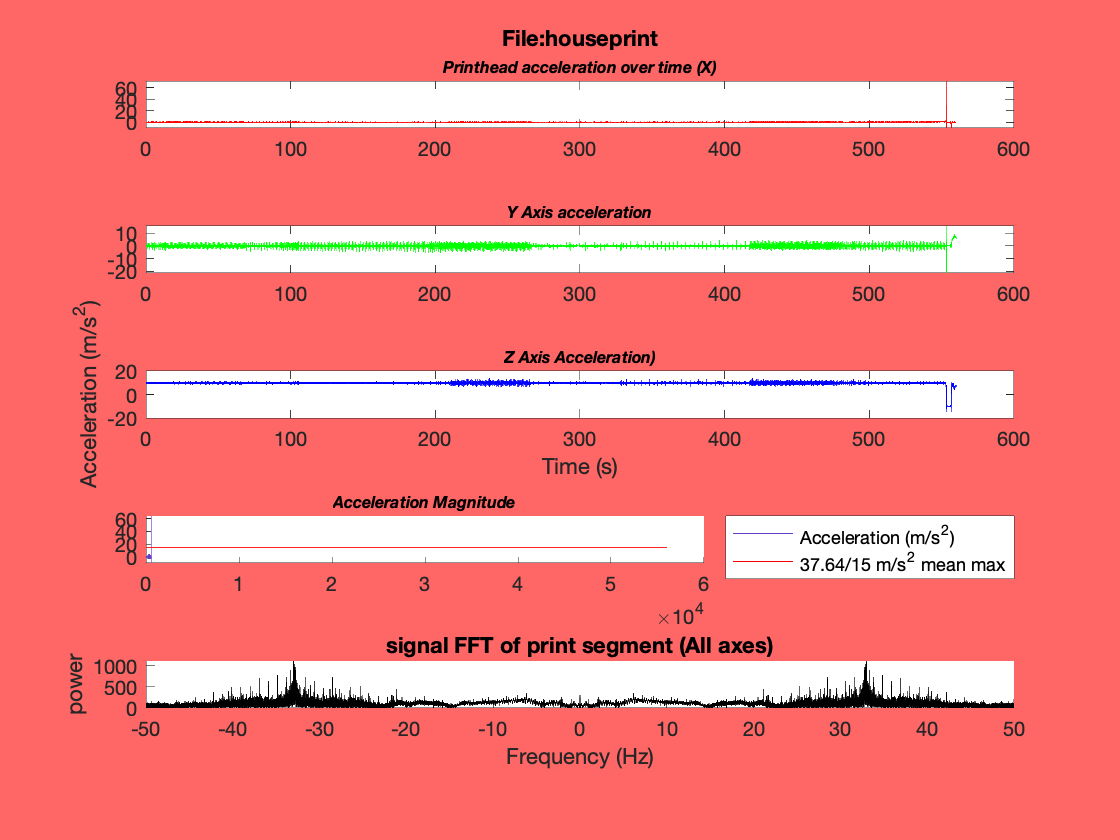

largest =     0.0199    0.0199    0.0185


success = logical
   0


success = logical
   0


level = 0.0195

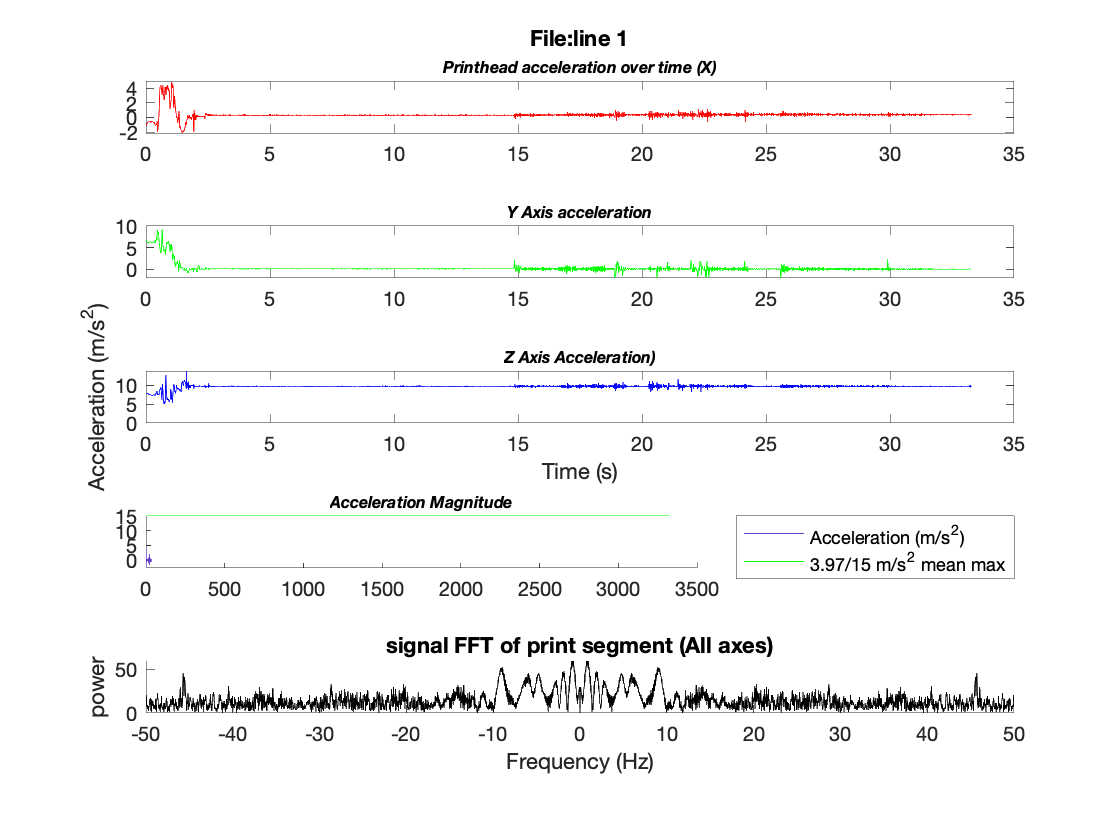

largest =     0.0178    0.0178    0.0177


success = logical
   1


success = logical
   1


level = 0.0178

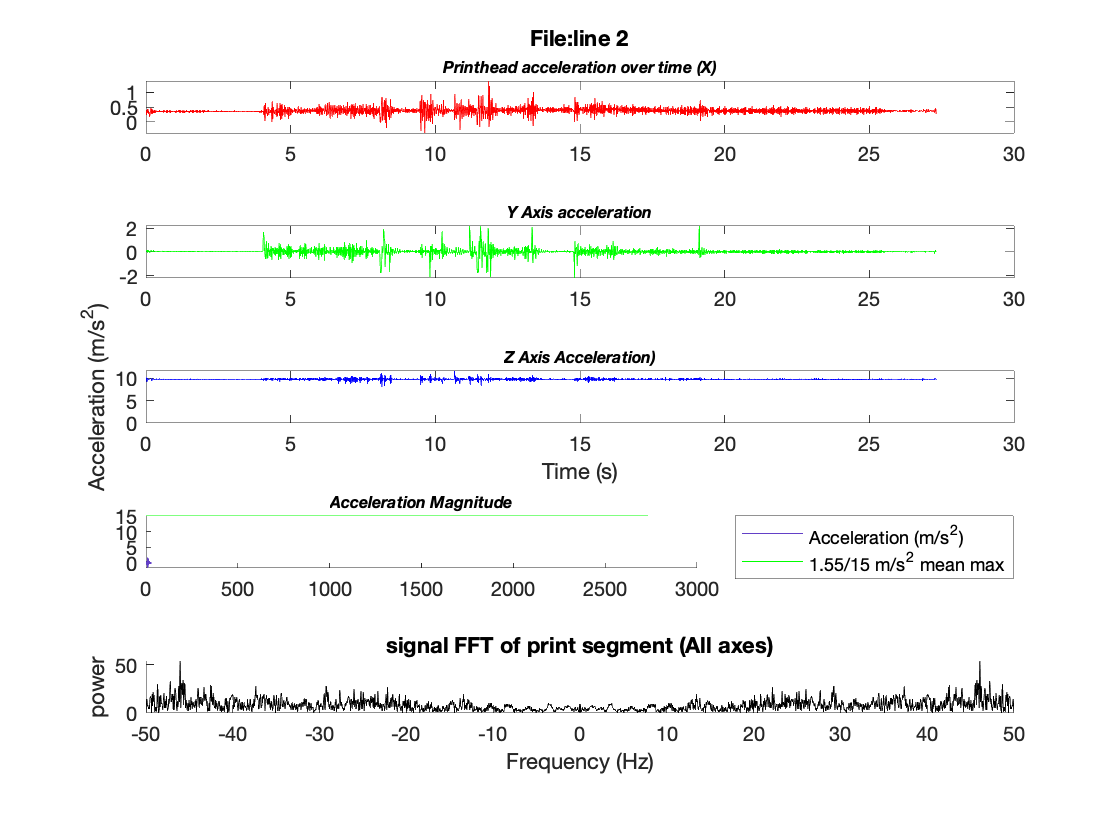

largest =     0.0102    0.0102    0.0101


success = logical
   1


success = logical
   1


level = 0.0101

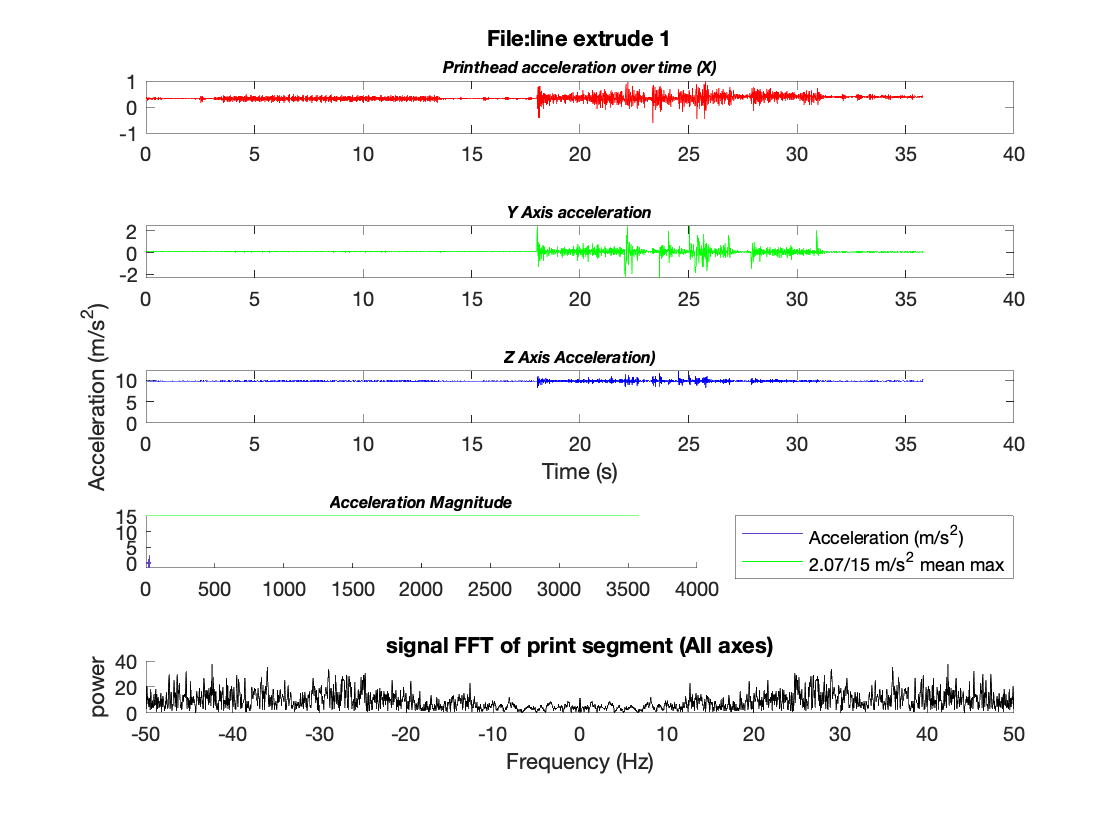

largest =     0.0093    0.0093    0.0092


success = logical
   1


success = logical
   1


level = 0.0093

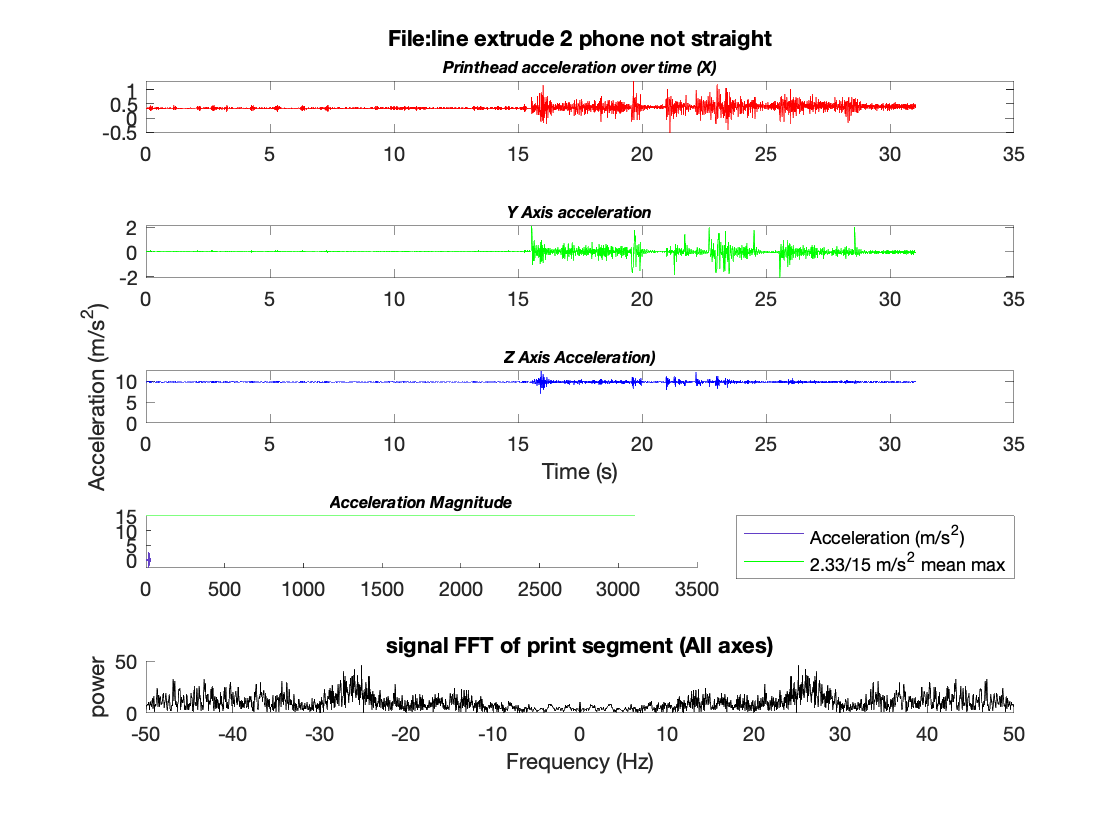

largest =     0.0148    0.0148    0.0136


success = logical
   1


success = logical
   1


level = 0.0144

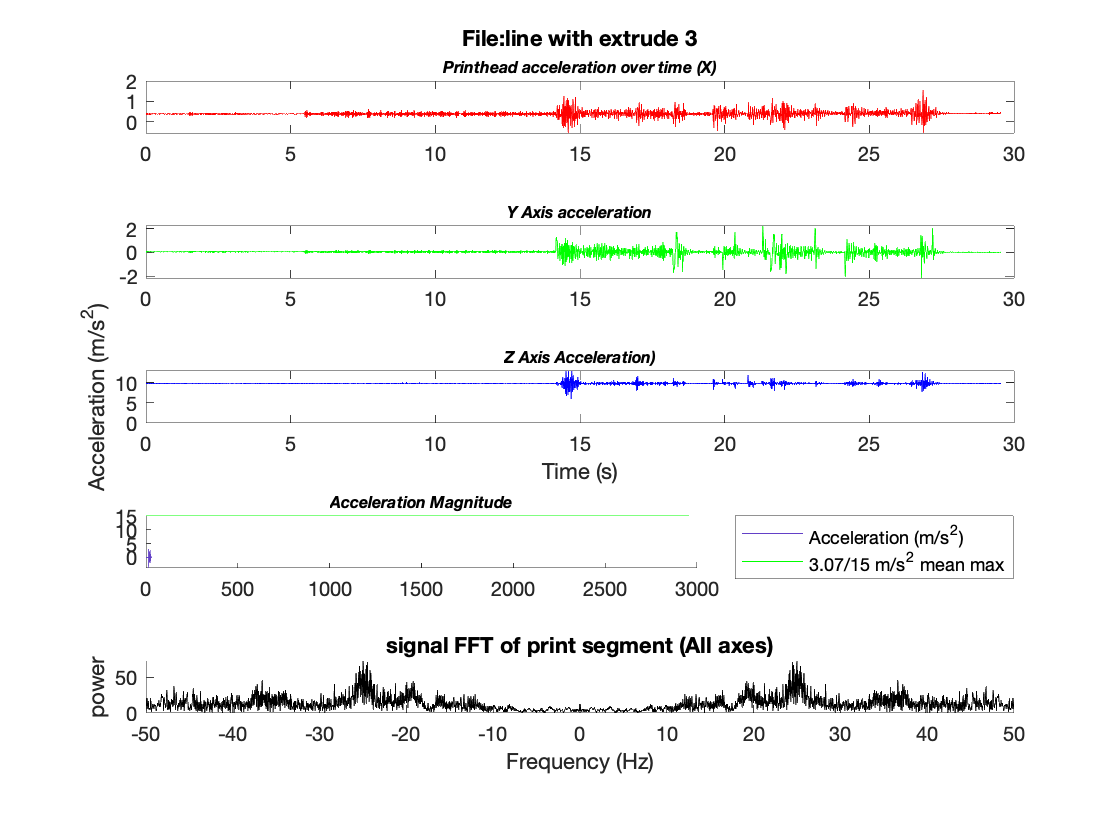

largest =     0.0247    0.0247    0.0242


success = logical
   0


success = logical
   0


level = 0.0245

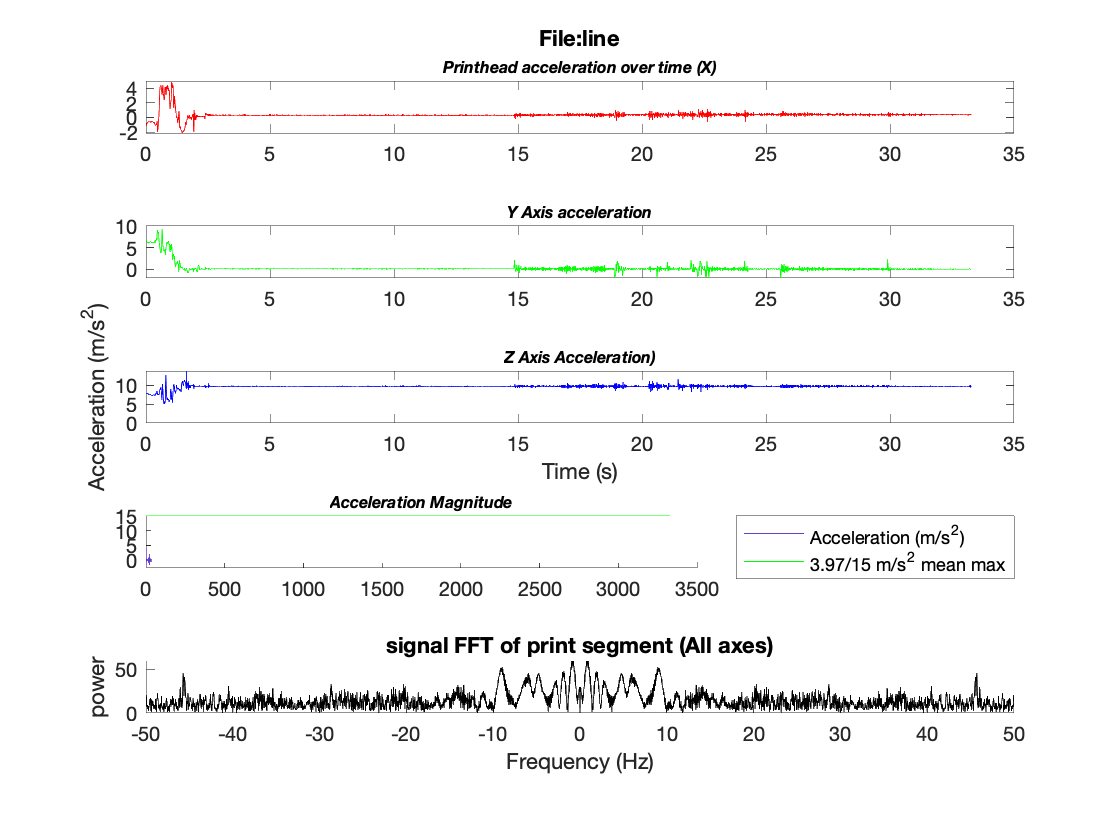

largest =     0.0178    0.0178    0.0177


success = logical
   1


success = logical
   1


level = 0.0178

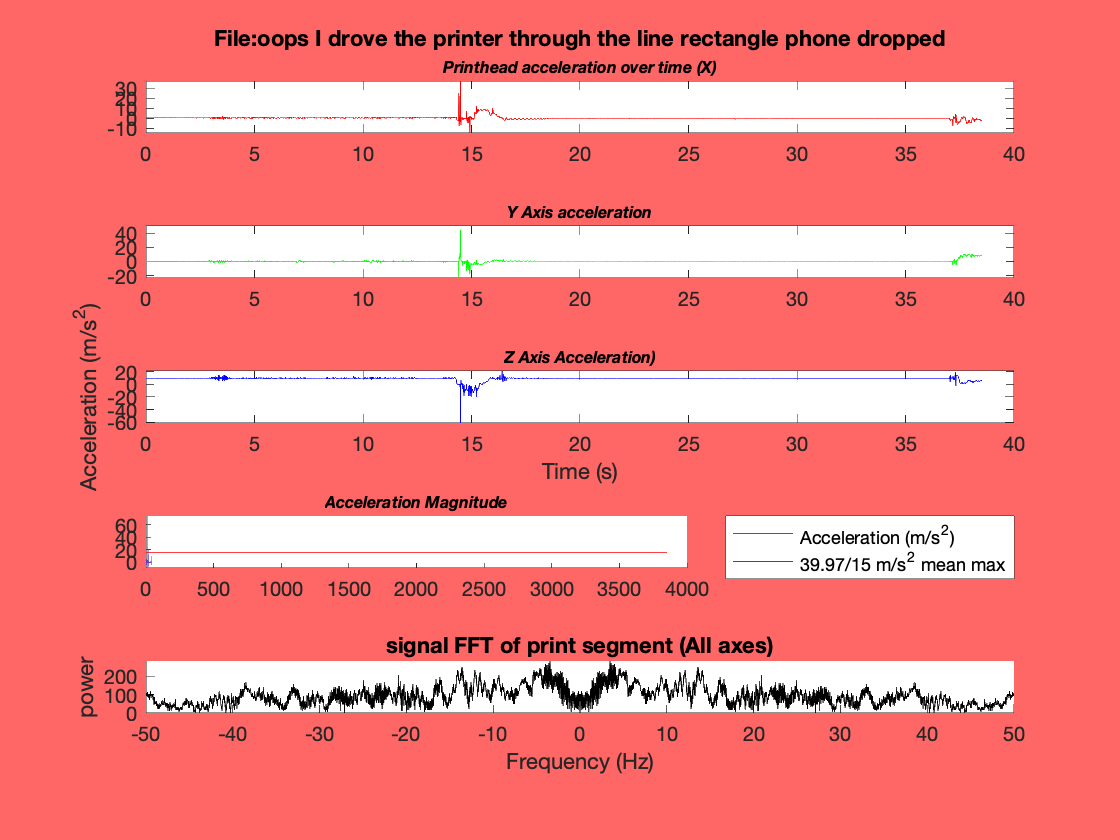

largest =     0.0730    0.0730    0.0704


success = logical
   0


success = logical
   0


level = 0.0722

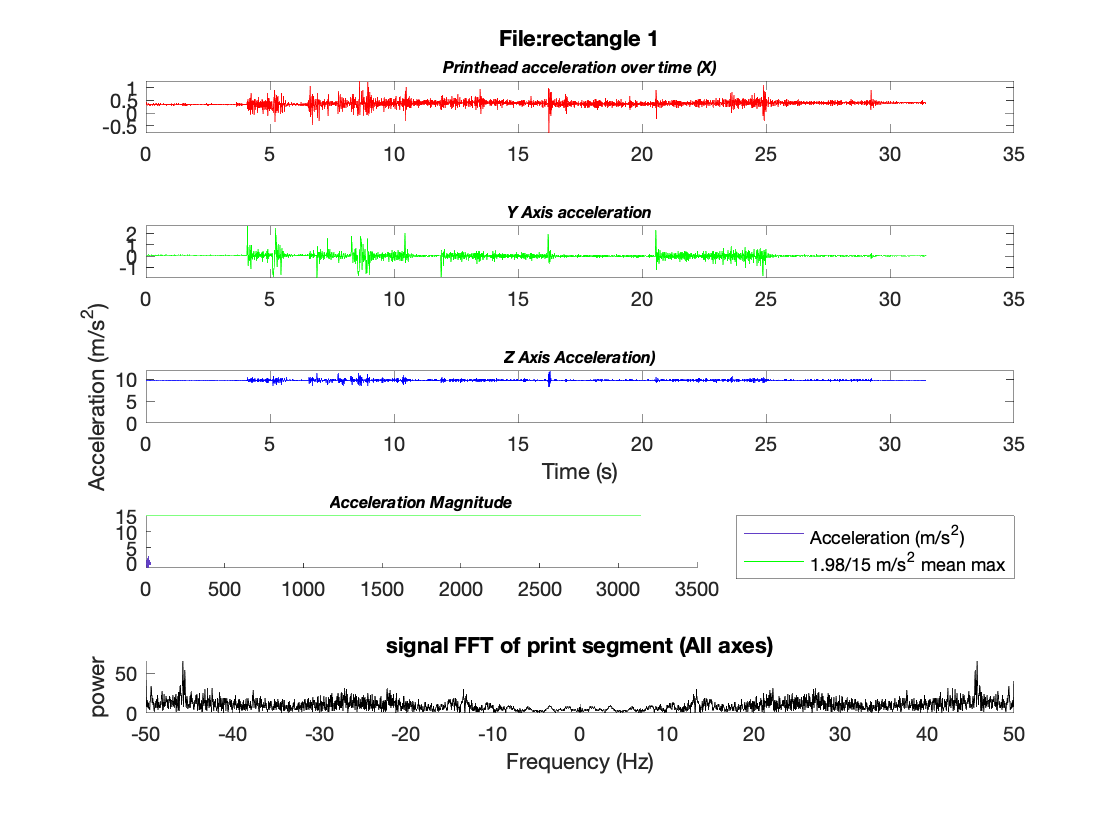

largest =     0.0100    0.0100    0.0097


success = logical
   1


success = logical
   1


level = 0.0099

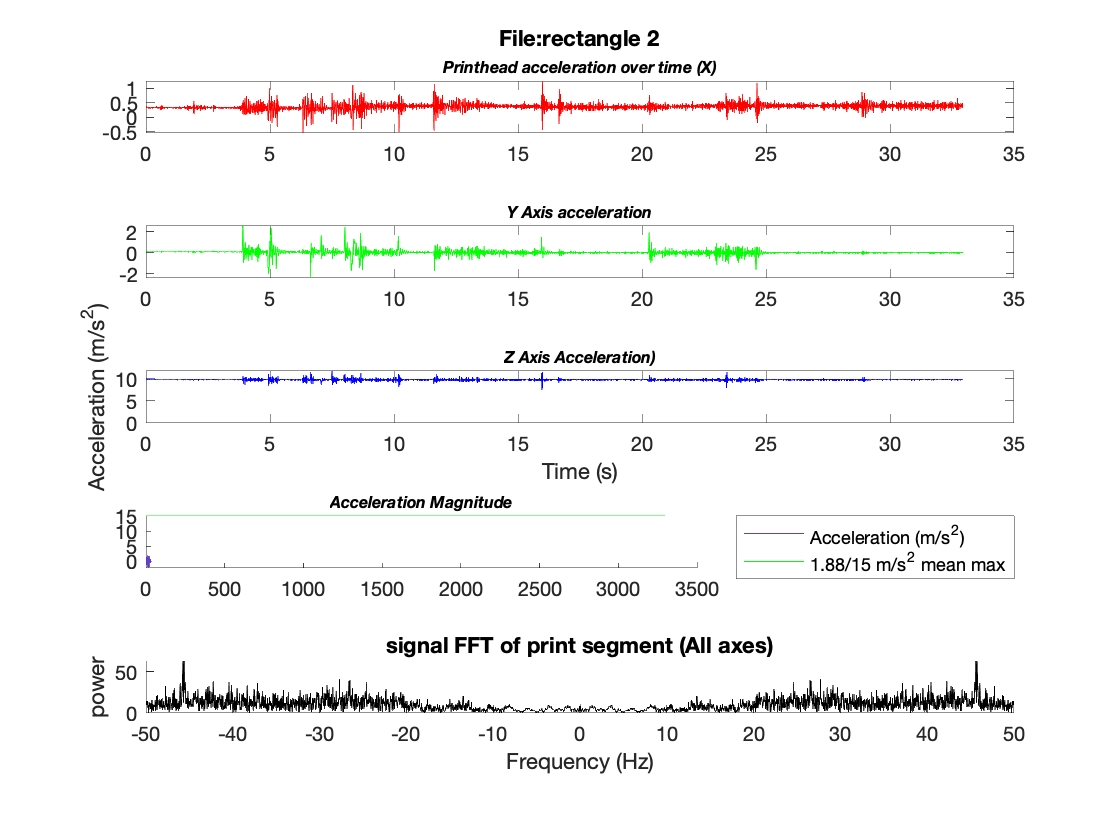

largest =     0.0124    0.0124    0.0120


success = logical
   1


success = logical
   1


level = 0.0123

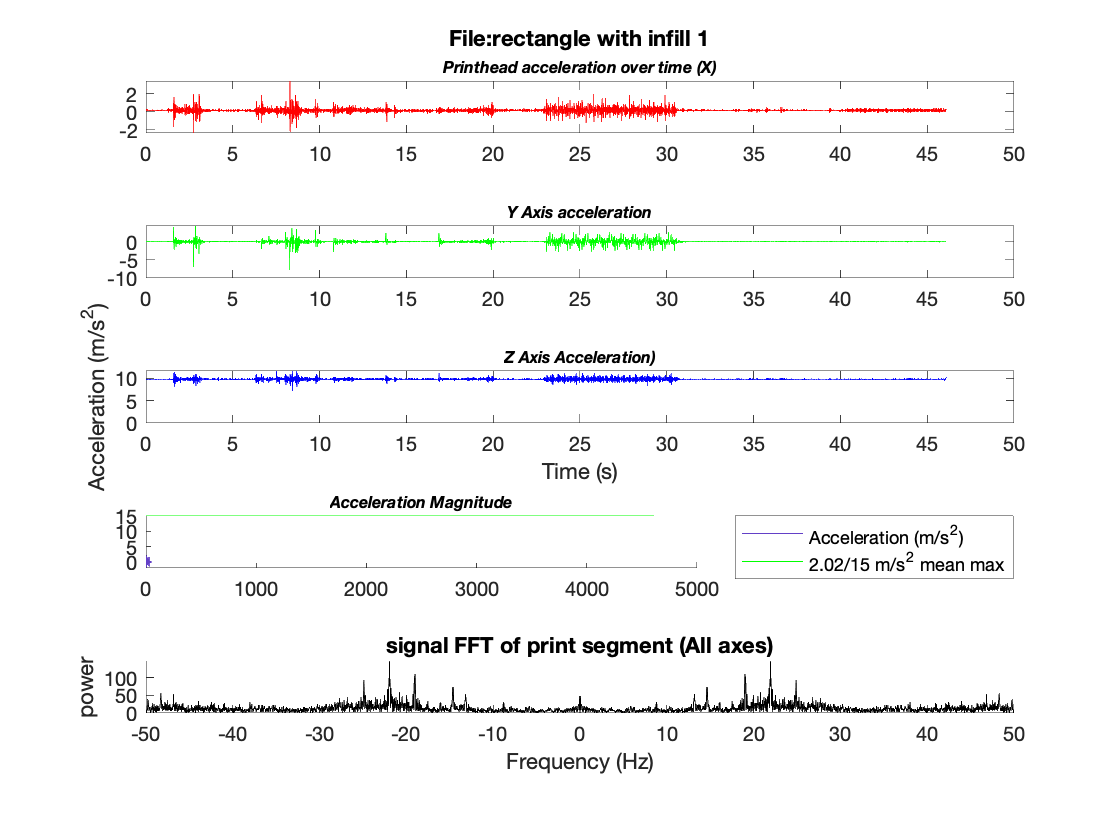

largest =     0.0318    0.0318    0.0312


success = logical
   0


success = logical
   0


level = 0.0316

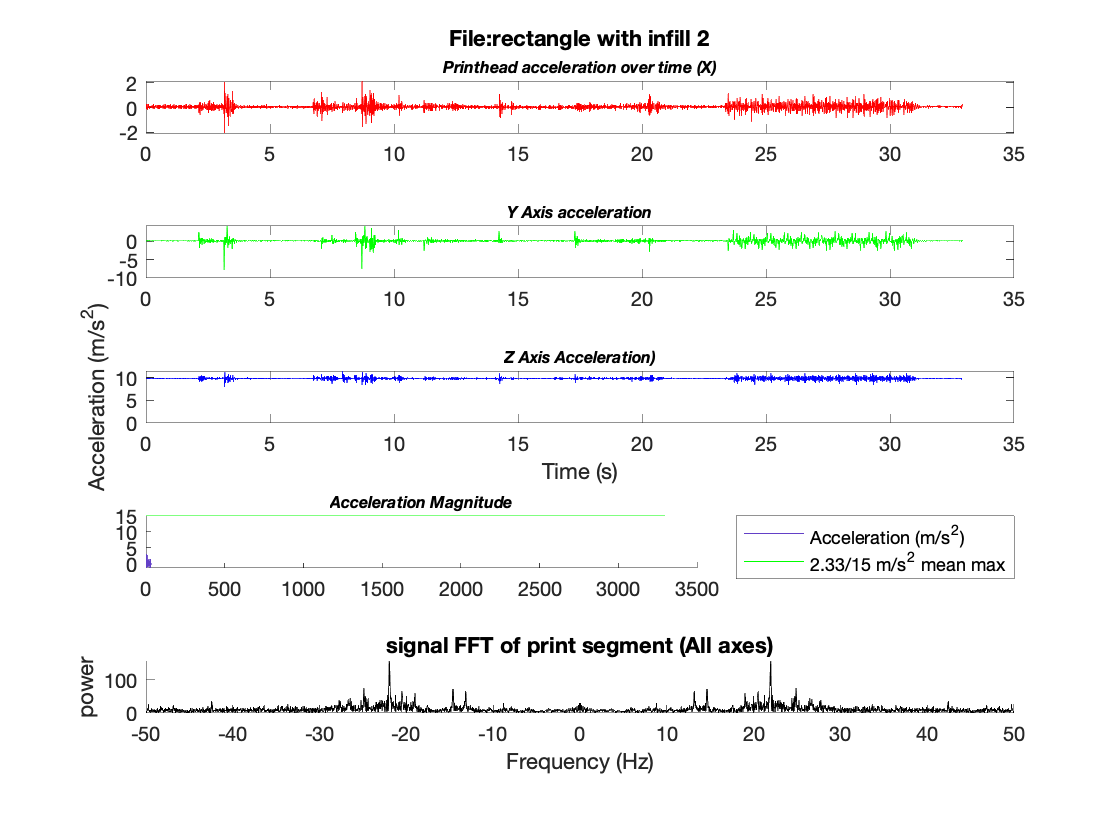

largest =     0.0478    0.0478    0.0447


success = logical
   0


success = logical
   0


level = 0.0468

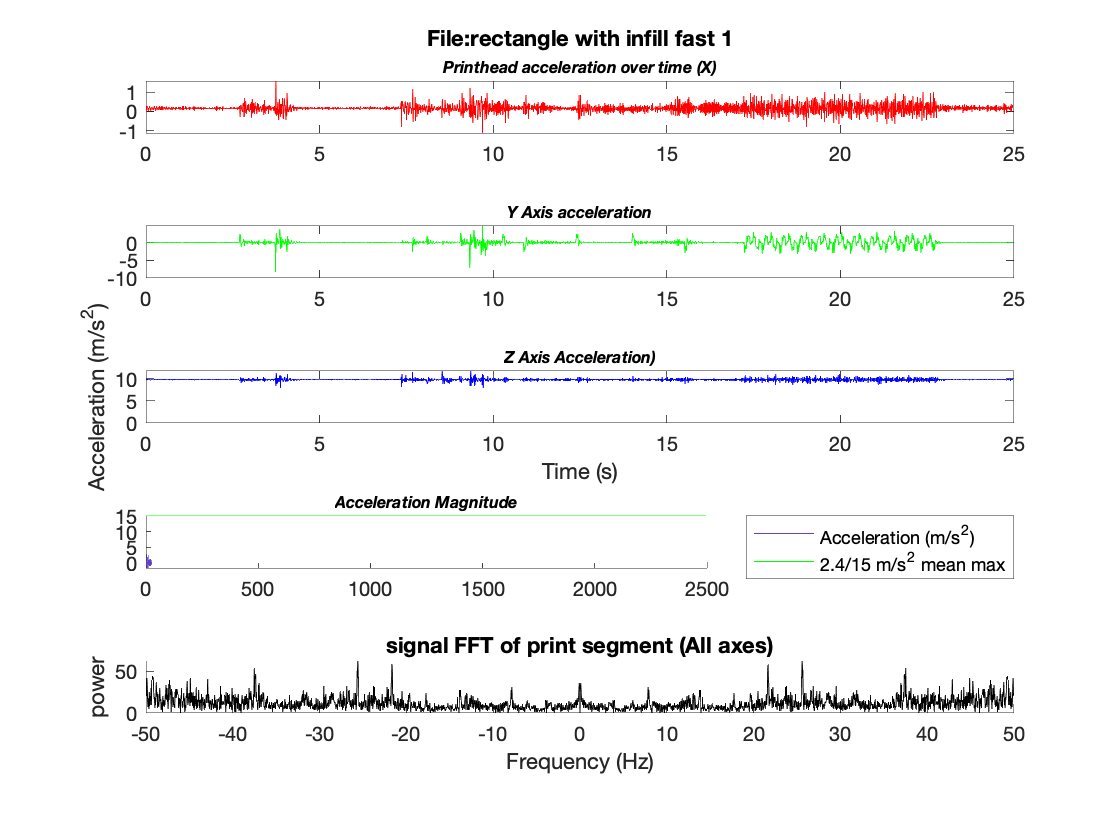

largest =     0.0250    0.0250    0.0233


success = logical
   0


success = logical
   0


level = 0.0244

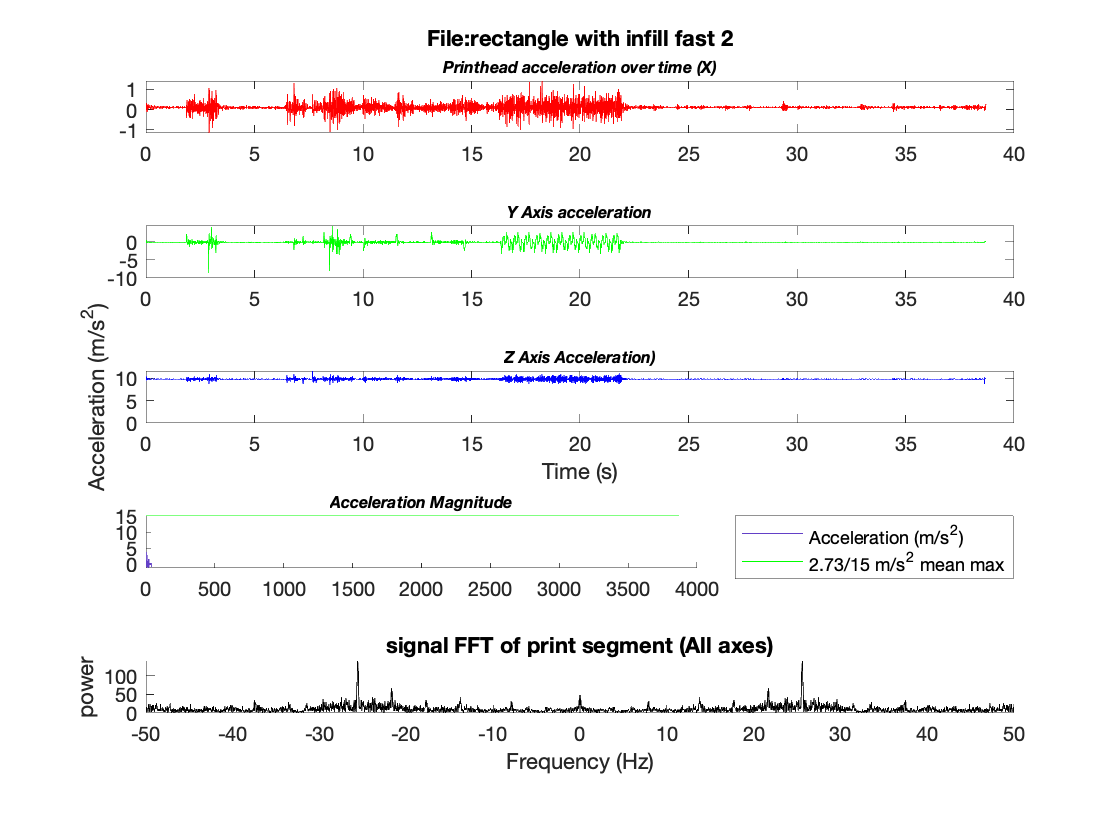

largest =     0.0362    0.0362    0.0353


success = logical
   0


success = logical
   0


level = 0.0359

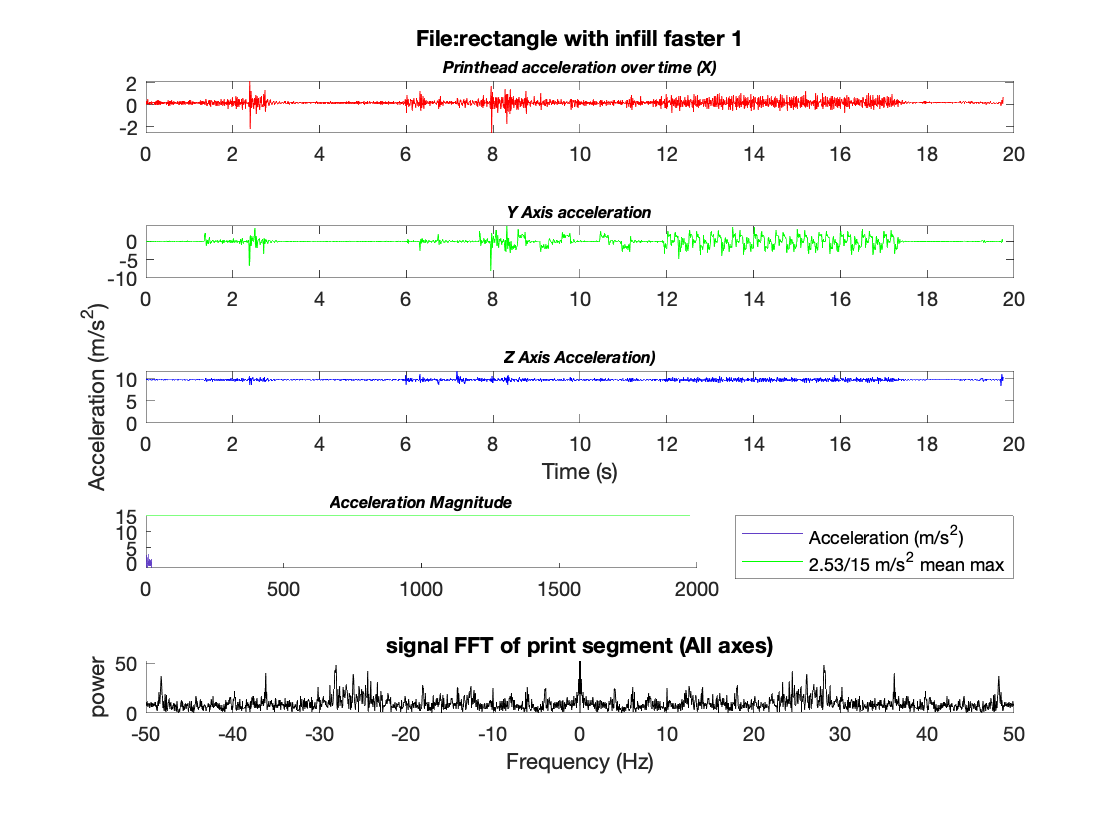

largest =     0.0263    0.0263    0.0243


success = logical
   0


success = logical
   0


level = 0.0257

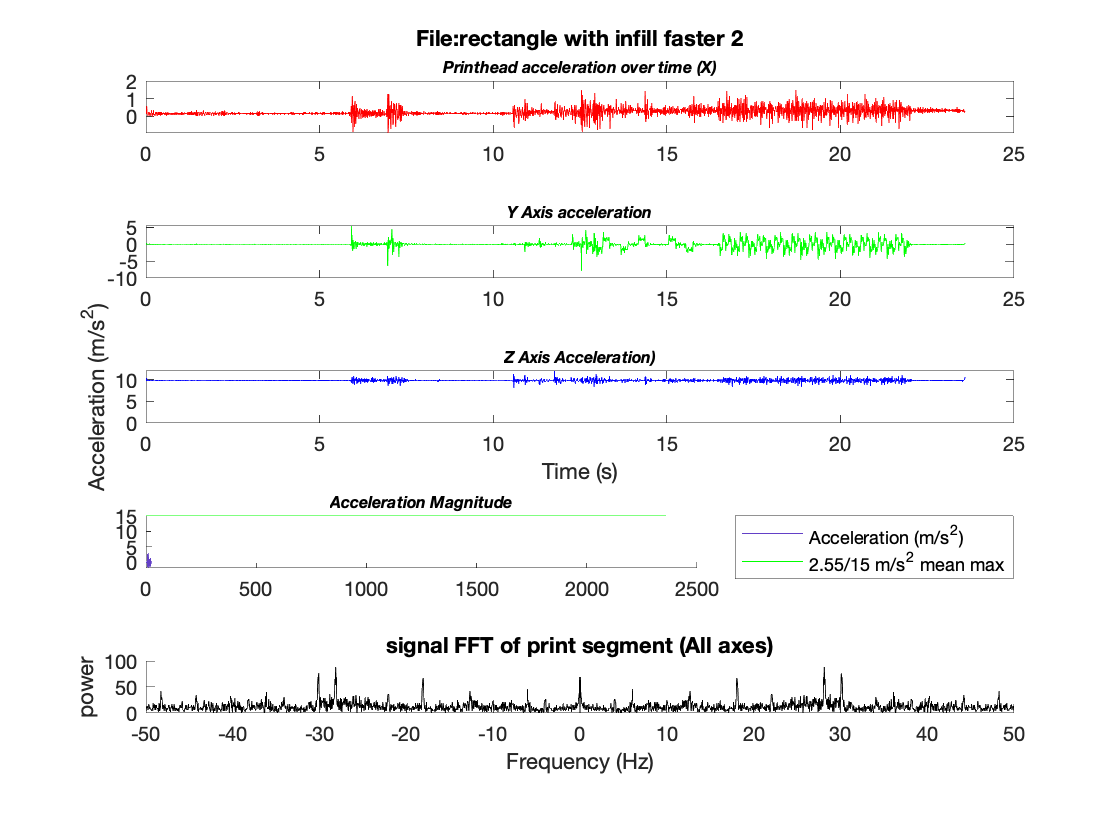

largest =     0.0375    0.0375    0.0321


success = logical
   0


success = logical
   0


level = 0.0357

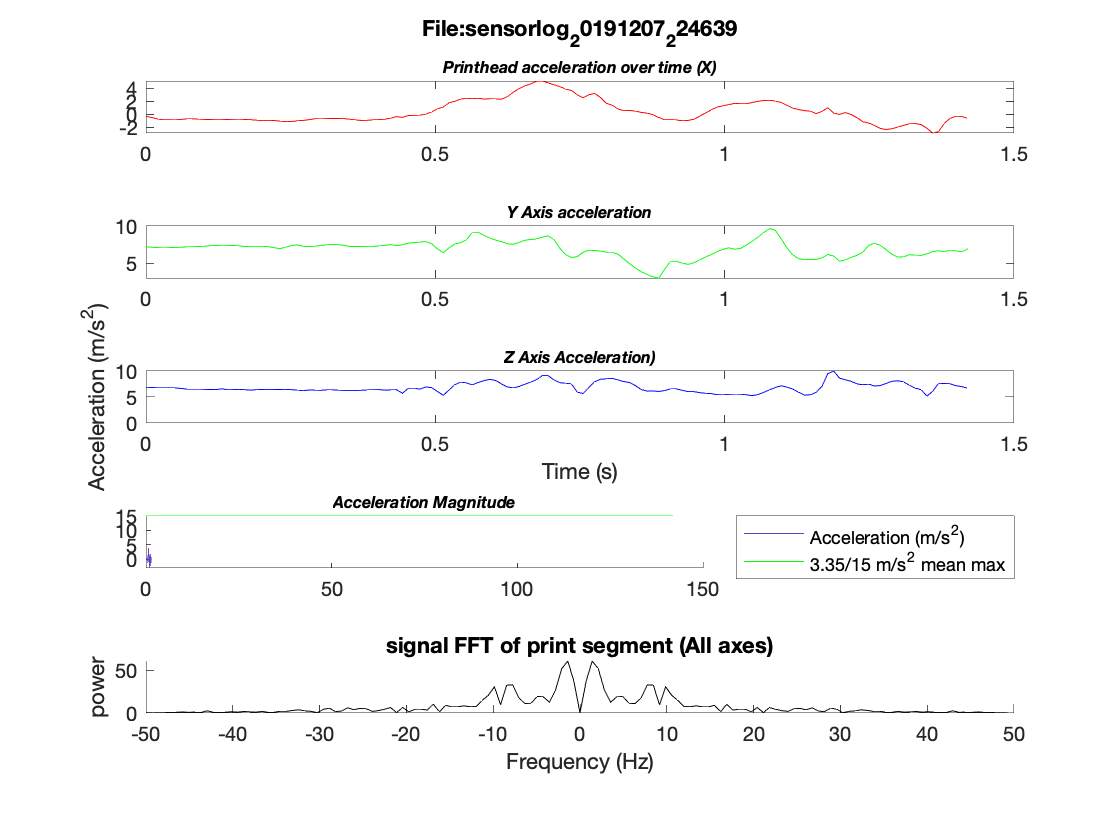

largest =     0.4288    0.4288    0.3645


success = logical
   0


success = logical
   0


level = 0.4074

tic
for k = 1:length(mydata)
    sample = mydata(k);
    Acceleration = sample{1}.Acceleration;
    t = linspace(0,height(Acceleration)/100,height(Acceleration));
    figure()
    a = timetable2table(Acceleration);
    accelData = [a.X a.Y a.Z]';
    
    subplot(5,1,1);
    plot(t,accelData(1,:), 'r')
    title({strcat('File: ',sample{1}.Source(1:end-4));"\fontsize{8}\itPrinthead acceleration over time (X)"})
    
    subplot(5,1,2);
    plot(t,accelData(2,:), 'g')
    title("\fontsize{8}\itY Axis acceleration")
    
    subplot(5,1,3);
    plot(t,accelData(3,:), 'b')
    title("\fontsize{8}\itZ Axis Acceleration)")
    xlabel("Time (s)")
    ylabel("Acceleration (m/s^2)")
    hold on;
    plot([0,0],[0,0])
    
    subplot(5,1,4);
    accelData = [a.X a.Y a.Z]';
    x = vecnorm(accelData);
    x = x - mean(x);
    hold on;
    plot(t,x, 'Color', [99, 64, 199]./255)
    title("\fontsize{8}\itAcceleration Magnitude")
    
    [success, level] = classify_accel_threshold(x);
    if success
        plot([0 length(x)], [15 15], 'g')
    legend('Acceleration (m/s^2)', strcat(string(round(level,2)),'/15 m/s^2 mean max'), 'Location', 'bestoutside')
    else
        plot([0 length(x)], [15 15], 'r')
        legend('Acceleration (m/s^2)', strcat(string(round(level,2)),'/15 m/s^2 mean max'), 'Location', 'bestoutside')
        set(gcf, 'color', [1 0.4 0.4])
    end
    hold off;
    
    subplot(5, 1, 5);
    N = length(x);
    Fs = 100; % sampling rate of 100Hz
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
    FA = fft(x);
    fftOutput = fftshift(abs(FA));
    hold on;
    plot(f,fftOutput,'Color',[0 0 0]./255);
    title("signal FFT of print segment (All axes)")
    xlabel("Frequency (Hz)")
    ylabel("power")
    hold off;
    sampleLength = length(fftOutput);
    normalizedSample = fftOutput./sampleLength;
    [success, level] = classify_fft_threshold(normalizedSample, 0.018)
%     saveas(gcf, strcat('./imgs/',sample{1}.Source(1:end-4),'.png'))
end

toc

Elapsed time is 3.659967 seconds.


## Run Simple Success Analysis